clc
clear all
close all

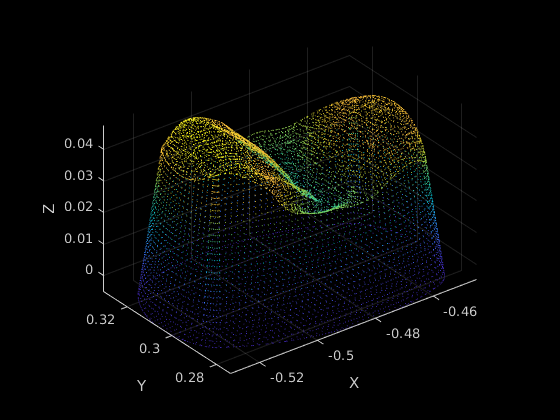

stlData = stlread('stl/1tooth_mesh2.STL');
points = stlData.Points;
ptCloud = pointCloud(points);

Sx = 0.01;
Sy = 0.01;
Sz = 0.01;
tform = affine3d([Sx 0 0 0; 0 Sy 0 0; 0 0 Sz 0; 0 0 0 1]);

% ptCloud_fin = pctransform(ptCloud,tform);
% rot = [1 0 0; 0 1 0; 0 0 1];
% trans = [0.7 -0.4 -0.1];
% tform = rigid3d(rot,trans);
ptCloud_fin = pctransform(ptCloud,tform);

%Plot full point cloud
figure
pcshow(ptCloud_fin)
hold on
xlabel('X'); ylabel('Y'); zlabel('Z');

Algo

- set Z range

- get Z -> getContour

- get ordered points -> getOrderedPoints()

- smoothen curve -> smoothCurve()

- Make polyshape

- Expand polyshape

figure
allPoints = {};
r = 0.005

r = 0.0050

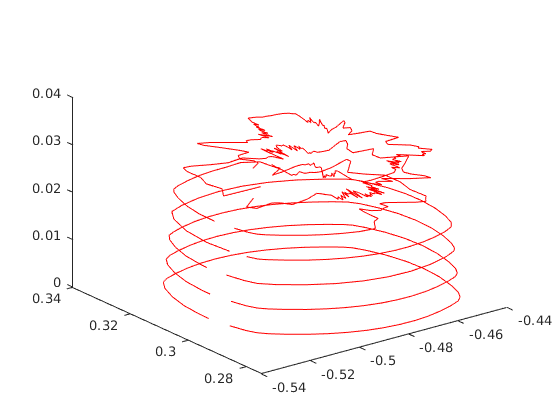

for i=1:7
    L = 0 + (i-1)*r;
    H = r + (i-1)*r;
    [a,b] = getContour(ptCloud_fin,L,H);
    P = getOrderedPoints(a,b);
    [smoothX,smoothY] = smoothCurve(P,35,2);
    
    points = downsample([smoothX',smoothY'],10);
   
    polyin = polyshape({points(:,1)},{points(:,2)});
    polyout = polybuffer(polyin,0.005);
    
    zin = (L+H)/2 * ones(length(polyin.Vertices),1);
    allPoints{i} = [points,zin];
%     zout = (L+H)/2 * ones(length(polyout.Vertices));
    
    plot3(polyin.Vertices(:,1),polyin.Vertices(:,2),zin,"Color",[1 0 0]); hold on;
%     plot3(polyout.Vertices(:,1),polyout.Vertices(:,2),zout,"Color",[0 1 0]);
end

a = 10

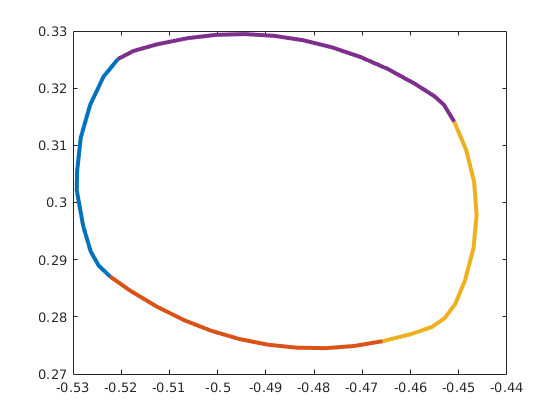

figure

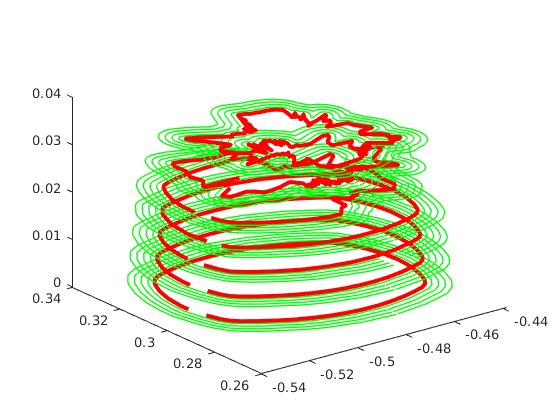

for i=1:length(allPoints)
    polyin = polyshape({allPoints{1,i}(:,1)},{allPoints{1,i}(:,2)});
    plot3(polyin.Vertices(:,1),polyin.Vertices(:,2),allPoints{1,i}(:,3),...
            "Color",[1 0 0],"LineWidth",3);
    hold on;
    for j=1:4
        polyout = polybuffer(polyin,0.002*j);
        polyout.Vertices = downsample(polyout.Vertices,5);
        z = allPoints{1,i}(1,3)*ones(length(polyout.Vertices),1);
        allPoints{j+1,i} = [polyout.Vertices, z];
        plot3(polyout.Vertices(:,1),polyout.Vertices(:,2),z,...
                "Color",[0 1 0],"LineWidth",1);
    end
end

curve1 = allPoints{5,1};

figure
[q1,q2,q3,q4] = getQuarters(allPoints{5,1},0);

function [a,b] = getContour(ptCloud,L,H)
k = 1;

for i = 1:length(ptCloud.Location(:,3))
    j = ptCloud.Location(i,3);
    if j < H && j > L
        a(k,1) = ptCloud.Location(i,1);
        b(k,1) = ptCloud.Location(i,2);
        k = k+1;
    end
end

end

function [P] = getOrderedPoints(a,b)
    P = [a'; b']; % coordinates / points 
    c = mean(P,2); % mean/ central point 
    d = P-c ; % vectors connecting the central point and the given points 
    th = atan2(d(2,:),d(1,:)); % angle above x axis
    [th, idx] = sort(th);   % sorting the angles 
    P = P(:,idx); % sorting the given points
    P = [P P(:,1)]; % add the first at the end to close the polygon 
end


function [smoothX, smoothY] = smoothCurve(P,windowWidth,polynomialOrder)
    smoothX = sgolayfilt(P(1,:), polynomialOrder, windowWidth);
    smoothY = sgolayfilt(P(2,:), polynomialOrder, windowWidth);
end

function [q1,q2,q3,q4] = getQuarters(curve1,flag)    
    a = floor(length(curve1)/4);
    curve1 = circshift(curve1,floor(a/2));
    curve1 = [curve1; curve1(1,:)];
    q1 = [curve1((1:a),1),curve1((1:a),2),curve1((1:a),3)];
    q2 = [curve1((a:2*a),1),curve1((a:2*a),2),curve1((a:2*a),3)];
    q3 = [curve1((2*a:3*a),1),curve1((2*a:3*a),2),curve1((2*a:3*a),3)];
    q4 = [curve1((3*a:end),1),curve1((3*a:end),2),curve1((3*a:end),3)];
    
    if(flag==1)
        plot3(q1(:,1),q1(:,2),q1(:,3),"LineWidth",3);hold on;
        plot3(q2(:,1),q2(:,2),q2(:,3),"LineWidth",3);hold on;
        plot3(q3(:,1),q3(:,2),q3(:,3),"LineWidth",3);hold on;
        plot3(q4(:,1),q4(:,2),q4(:,3),"LineWidth",3);hold on;
    end
end